%Load the "UPenLPIdistributionsSet" WorkSpace
load('WorkDataSets.mat')

%Outliers Removal
pattern = ["MozzT2"];
idx = contains(TCLaplaceTab.Row,pattern);
TCLaplaceTab(idx,:) = [];

%Pre Processing
curves = zeros(1129,height(ShelfLifeTrain));
for k = 1:height(ShelfLifeTrain)
    curves(:,k) = ShelfLifeTrain.Data{k}; 
end
curves = curves';
curves = normalize(curves);
time = ValidationTable.Time{1};

curvesValidationSet = zeros(1129,height(ShelfLifeValid)); %extraction of the curves from the validation set
for k = 1:height(ShelfLifeValid)
    curvesValidationSet(:,k) = ShelfLifeValid.Data{k}; 
end
curvesValidationSet = curvesValidationSet';
curvesValidationSet = normalize(curvesValidationSet);

%Stepwise useless variables removal
curves(:,826:end) = []; %step1
time(826:end) = [];      %high noisy data
curvesValidationSet(:,826:end) = [];

curves(:,1:5) = []; %last noisy data
time(1:5) = [];
curvesValidationSet(:,1:5) = [];

curves(:,idxVIP) = []; %remove all variables with VIP score < 1
time(idxVIP) = [];
curvesValidationSet(:,idxVIP) = [];

curves(:,221:end) = []; %last noisy data
time(221:end) = [];
curvesValidationSet(:,221:end) = [];

curves(:,idxRegCoef) = []; %remove all variables with reg.coefs < |1|
time(idxRegCoef) = [];
curvesValidationSet(:,idxRegCoef) = [];

curves(:,idxRegCoef) = []; %remove all variables with reg.coefs < |2|
time(idxRegCoef) = [];
curvesValidationSet(:,idxRegCoef) = [];

curves(:,idxRegCoef) = []; %remove all variables with reg.coefs < |3|
time(idxRegCoef) = [];
curvesValidationSet(:,idxRegCoef) = [];

curves(:,idxRegCoef) = []; %remove all variables with reg.coefs < |3|
time(idxRegCoef) = [];
curvesValidationSet(:,idxRegCoef) = [];

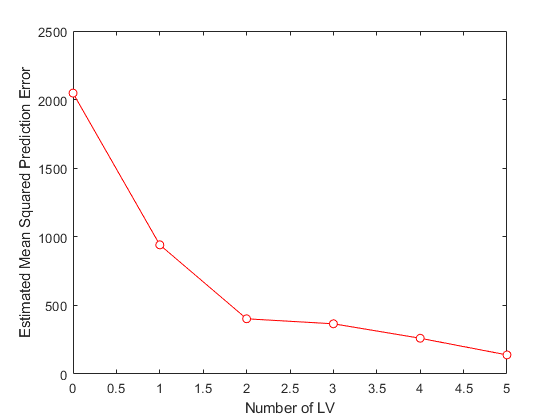

%Partial Leat Squares Regression (PLSR)
cvpart = cvpartition(ShelfLifeTrain.FrozenCurdPercent,'LeaveOut');
%partition of training set for crossvalidation
ncomp = 5; %number of pls latent variables

[XL,YL,XS,YS,BETA,PCTVAR,MSPE,stats] = plsregress(curves,ShelfLifeTrain.FrozenCurdPercent,ncomp,"cv",cvpart);

%MSEP plot vs. n° of LV to have a look on optimal LV number
cla reset
plot(0:ncomp,MSPE(2,:),'-or','MarkerFaceColor',"auto");
xlabel('Number of LV');
ylabel('Estimated Mean Squared Prediction Error');

min(MSPE(2,:)) %minimum MSPE

ans = 139.0250

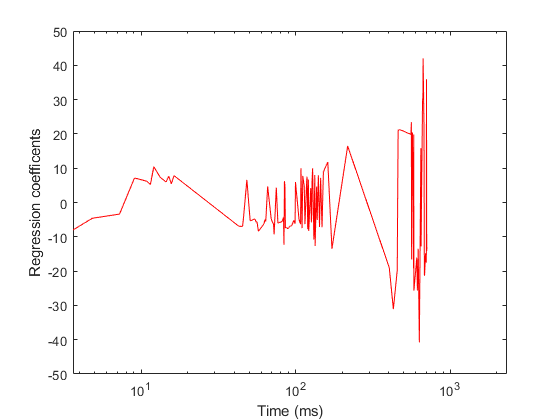

%Plot of regression coefficents against varaibles
semilogx(time,BETA(2:end),'r-')
xlabel("Time (ms)")
ylabel("Regression coefficents");
xlim([0 2330]);

%Selection of thershold for removal of useless variables
idxRegCoef = find(abs(BETA(2:end))<4);
idxLV1w = find(abs(XL(:,1))<1);
idxLV2w = find(abs(XL(:,2))<1);
idxVIP = find(vipScores<1);

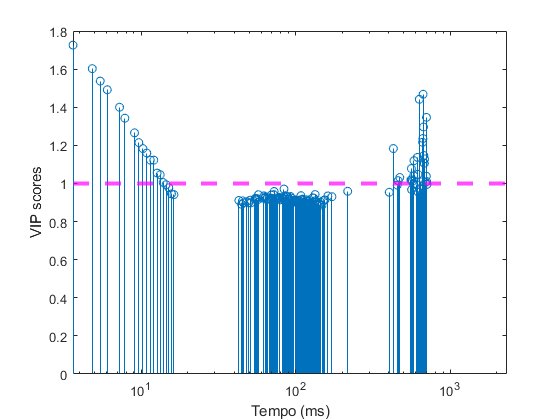

%Visual Importance Projection (VIP) scores
% Calculate normalized PLS weights
W0 = bsxfun(@rdivide,stats.W,sqrt(sum(stats.W.^2,1)));
% Calculate the product of summed squares of XS and YL
sumSq = sum(XS.^2,1).*sum(YL.^2,1);
% Calculate VIP scores for NCOMP components
vipScores = sqrt(size(XL,1) * sum(bsxfun(@times,sumSq,W0.^2),2) ./ sum(sumSq,2));
%VIP scores plot
cla reset
stem(time,vipScores);
set(gca,'xscale','log');
xlim([0 2330]);
ylabel("VIP scores");
xlabel("Tempo (ms)");
yline(1,'m--','LineWidth',3);

%it points out that the most important area of the relaxation curve is the 
%one between 10 and 20 ms which should be chemical exchange relaxation
%field between protein network and water protons

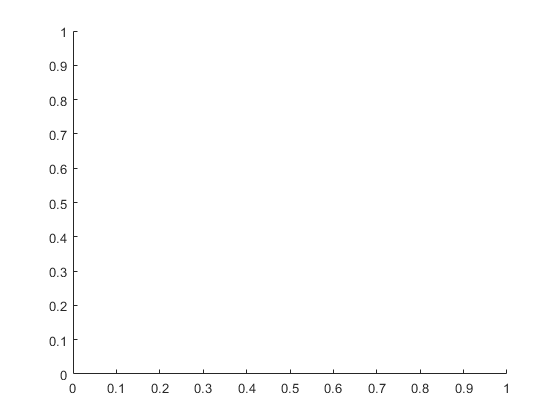

%plot of normalized (zscore) categories
cla reset

semilogx(time,variables(k,:),'-r');

Undefined function or variable 'variables'.


hold on
semilogx(time,variables(7,:),'-g');
semilogx(time,variables(16,:),'b-');
semilogx(time,variables(23,:),'k-');
xlim([2 15050]);
legend({'0' '15' '30' '50'});
hold off

%Plot of LV loadings against variables
%the plot of predictors (X) loadings vs. variables as well as the 
%regression coefficents vs. variables enables to see which
%variables are the most significant for the prediction (where the
%corresponding loading or coefficent has an high absolute value)
cla reset
semilogx(time,XL(:,1),'.r')
hold on                                                  
semilogx(time,XL(:,2),'.g')        
semilogx(time,XL(:,3),'.b')     
semilogx(time,XL(:,4),'.k')       
semilogx(time,XL(:,5),'.m')  
% semilogx(time,XL(:,6),'-c')
xlabel("tempo (ms)")
xlim([0 2400]);
ylabel("X loadings");
legend({'LV1' 'LV2' 'LV3' 'LV4' 'LV5' 'LV6'},'Location','northeastoutside');

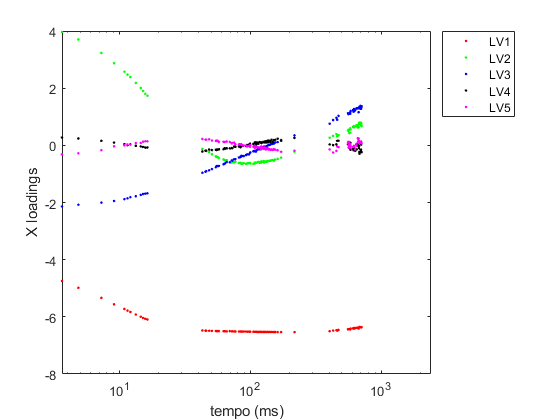

hold off

%PLSR crossvalidation
FrozenCurd = ShelfLifeTrain.FrozenCurdPercent;
predictedY = zeros(height(ShelfLifeTrain),1);
predictionlogicarray = zeros(height(ShelfLifeTrain),1);
regresscoeff = zeros(length(XL)+1,height(ShelfLifeTrain));
LV1w = zeros(length(XL),height(ShelfLifeTrain));
LV2w = zeros(length(XL),height(ShelfLifeTrain));
mspetrain = zeros(43,1);
for k = 1:length(predictedY)
    idxTrain = training(cvpart,k);
    idxTest = test(cvpart,k);
    dataTest = curves(idxTest,:);
    [xl,~,~,~,betacv,~,mspe,~] = plsregress(curves(idxTrain,:),FrozenCurd(idxTrain,:),ncomp);
    predictedY(k,:) = [ones(size(dataTest,1),1) dataTest]*betacv;
    regresscoeff(:,k) = betacv;%gathering regress coefficents of cv model for jack knife
    LV1w(:,k) = xl(:,1); %gathering lv1 weigths of cv model for jack knife
    LV2w(:,k) = xl(:,2); %gathering lv2 weights of cv model for jack knife
    mspetrain(k,1) = mspe(2,6);
end

testorder = zeros(height(ShelfLifeTrain),1); 
%order of test samples which are predicted so it's possible to know 
%the actual and the predicted value for that test set
for k=1:length(testorder)
    testorder(k) = FrozenCurd(test(cvpart,k));
end
cvprediction = [testorder predictedY];

mean(mspetrain)

ans = 58.1209

std(mspetrain)

ans = 2.3669

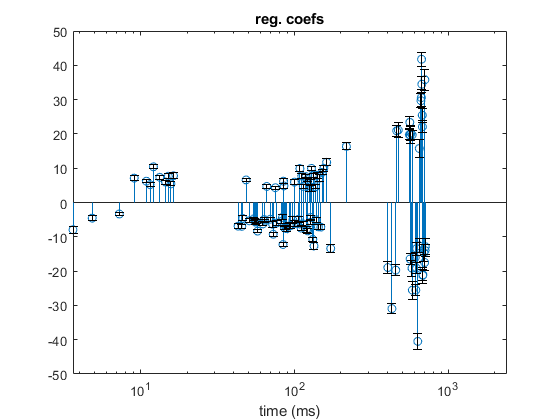

%Jack Knife on Regression Coefficent
%Jack Knifing: during crossvalidation for each partition fold a new model is
%created together with new loadings, MSPE, regression coefficents, etc. so
%knowing that regression coefficents (as loadings) the bigger they are (in 
%absolute value) and the higher is their importance for prediction, by
%at the mean +/- std of the regression coefficent of each variable
%it is possible to discart of the ones closest to zero (also with std range
%including zero) in a step-wise way (one variable at time is suggested).
JackMean = mean(regresscoeff(2:end,:),2);             
JackStd = std(regresscoeff(2:end,:),0,2); 
cla reset
stem(time,JackMean')
xlim([0 2400]);
xlabel("time (ms)");
set(gca,'xscale','log');
hold on                                              
er = errorbar(time,JackMean,JackStd,JackStd);       
er.Color = [0 0 0];                                 
er.LineStyle = 'none';  
title("reg. coefs");
hold off

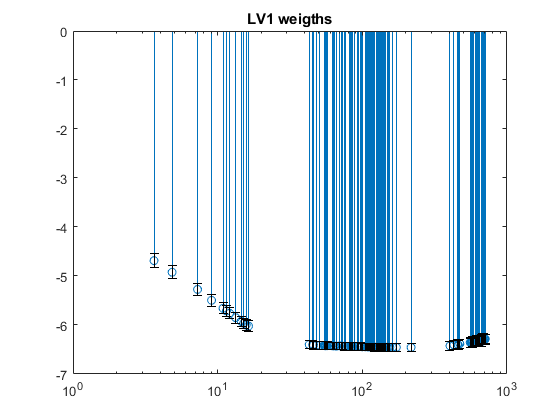


JackLV1avg = mean(LV1w,2);             
JackLV1std = std(LV1w,0,2); 
cla reset
stem(time,JackLV1avg') 
set(gca,'xscale','log');
hold on                                              
er = errorbar(time,JackLV1avg,JackLV1std,JackLV1std);       
er.Color = [0 0 0];                                 
er.LineStyle = 'none'; 
title("LV1 weigths");
hold off

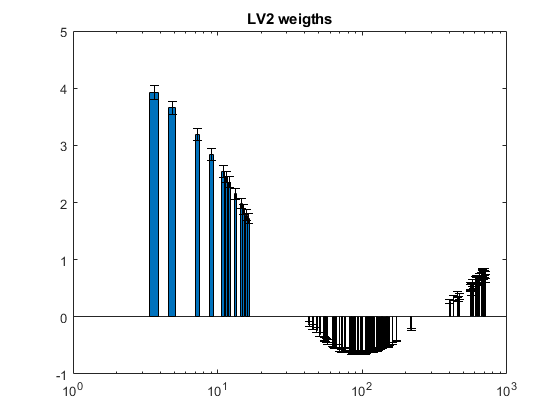


JackLV2avg = mean(LV2w,2);             
JackLV2std = std(LV2w,0,2); 
cla reset
bar(time,JackLV2avg') 
set(gca,'xscale','log');
hold on                                              
er = errorbar(time,JackLV2avg,JackLV2std,JackLV2std);       
er.Color = [0 0 0];                                 
er.LineStyle = 'none'; 
title("LV2 weigths");
hold off

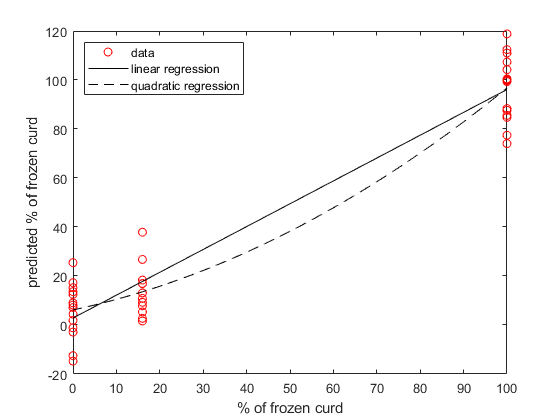

%correlation between actual and predicted values
[linearegress,gof] = fit(testorder,predictedY,'poly1');
[quadraticregress,gof2] = fit(testorder,predictedY,'poly2');

%plot of the correlation between actual and predicted value
cla reset
plot(testorder,predictedY,'ro')
hold on
plot(linearegress,'-k')
plot(quadraticregress,'--k')
xlabel('% of frozen curd');
ylabel('predicted % of frozen curd');
legend({'data','linear regression','quadratic regression'},"Location","northwest");
hold off

Rsquaredlinear = gof.rsquare

Rsquaredlinear = 0.9289

Rsquaredquadratic = gof2.rsquare

Rsquaredquadratic = 0.9341

%Validation of the model
predictedValidation = [ones(height(ShelfLifeValid),1) curvesValidationSet]*BETA;
%calculation of the predicted quantity of frozen curd multiplying variables with
%the pls coefficents
XScores_Valid = curvesValidationSet*stats.W;

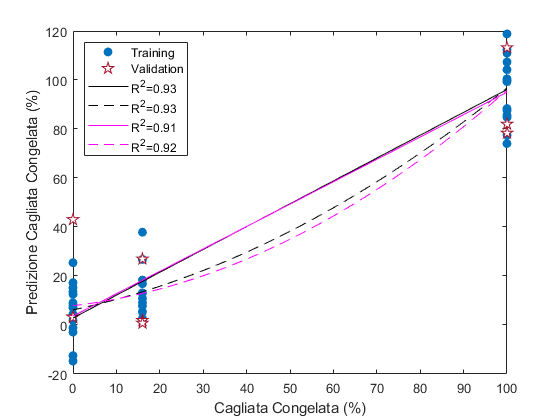

%correlation between actual and predicted values
[linearegress,gof] = fit(testorder,predictedY,'poly1');
[quadraticregress,gof2] = fit(testorder,predictedY,'poly2');
xV = [0 0 0 16 16 16 100 100 100];
xV = [testorder ; xV'];
yV = [predictedY ; predictedValidation];
[linearegressVal,Vgof] = fit(xV,yV,'poly1');
[quadraticregressVal,Vgof2] = fit(xV,yV,'poly2');

%plot of the correlation between actual and predicted value
cla reset
plot(testorder,predictedY,'o','MarkerFaceColor',[0 0.4470 0.7410])
hold on
plot([0 0 0 16 16 16 100 100 100], predictedValidation,'p', 'MarkerSize',9,'MarkerEdgeColor',[0.6350 0.0780 0.1840],'MarkerFaceColor',[1 1 1])
plot(linearegress,'-k')
plot(quadraticregress,'--k')
plot(linearegressVal,'-m')
plot(quadraticregressVal,'--m')
xlabel('Cagliata Congelata (%)');
ylabel('Predizione Cagliata Congelata (%)');
legend({'Training','Validation','R^{2}=0.93','R^{2}=0.93','R^{2}=0.91','R^{2}=0.92'},"Location","northwest");
hold off

Vgof.rsquare

ans = 0.9081

Vgof2.rsquare

ans = 0.9167

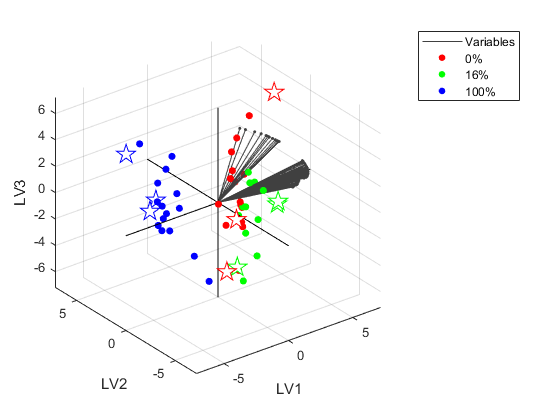

h = biplot(XL(:,1:3),"Scores",XS(:,1:3));
hold on
h2 = biplot(XL(:,1:3),"Scores",XScores_Valid(:,1:3));
hold off
for k = 1:109
h(k).Color = [0.25 0.25 0.25];
end
for k = 110:218
    h(k).Color = [0.25 0.25 0.25];
end

for k = 1:109
h2(k).Color = [0.25 0.25 0.25];
end
for k = 110:218
    h2(k).Color = [0.25 0.25 0.25];
end

for k = 219:233
    h(k).Color = 'r';
    h(k).MarkerSize = 15;
end
for k = 234:247
    h(k).Color = 'g';
    h(k).MarkerSize = 15;
end

for k = 248:262
    h(k).Color = 'b';
    h(k).MarkerSize = 15;
end

for k = 219:221
    h2(k).MarkerEdgeColor = 'r';
    h2(k).MarkerSize = 15;
    h2(k).MarkerFaceColor = [1 1 1];
    h2(k).Marker = 'p';
end
for k = 222:224
    h2(k).MarkerEdgeColor = 'g';
    h2(k).MarkerSize = 15;
    h2(k).MarkerFaceColor = [1 1 1];
    h2(k).Marker = 'p';
end
for k = 225:227
    h2(k).MarkerEdgeColor = 'b';
    h2(k).MarkerSize = 15;
    h2(k).MarkerFaceColor = [1 1 1];
    h2(k).Marker = 'p';
end
xlabel("LV1");
ylabel("LV2");
zlabel("LV3");
legend([h(1) h(233) h(247) h(262)],{'Variables','0%','16%','100%'});

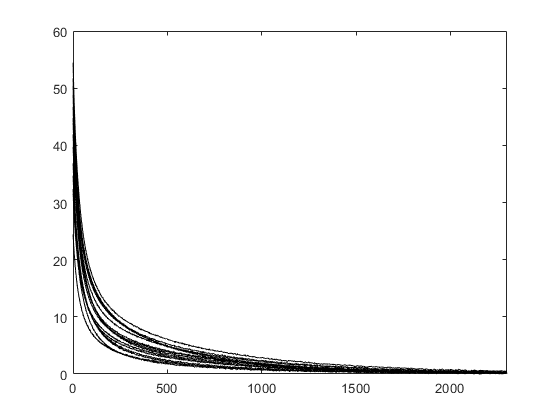

for k = 16:30
plot(ShelfLifeTrain.Time{1},ShelfLifeTrain.Data{k},'-k')
hold on
end
ylim([0 60]);
xlim([0 2300]);
hold off

curve = zeros(1129,15);
for k = 16:30
curve(:,k) = ShelfLifeTrain.Data{k};
end
curve(:,1:15) = [];
curve = curve';
curve = normalize(curve);
[coeff,score,latent,tsquared,explained] = pca(curve);

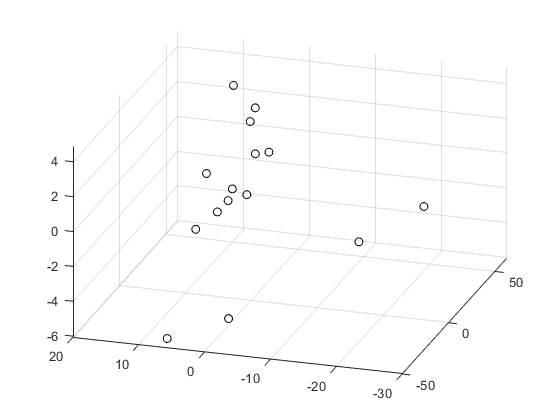

cla reset
scatter3(score(:,1),score(:,2),score(:,3),'ok')